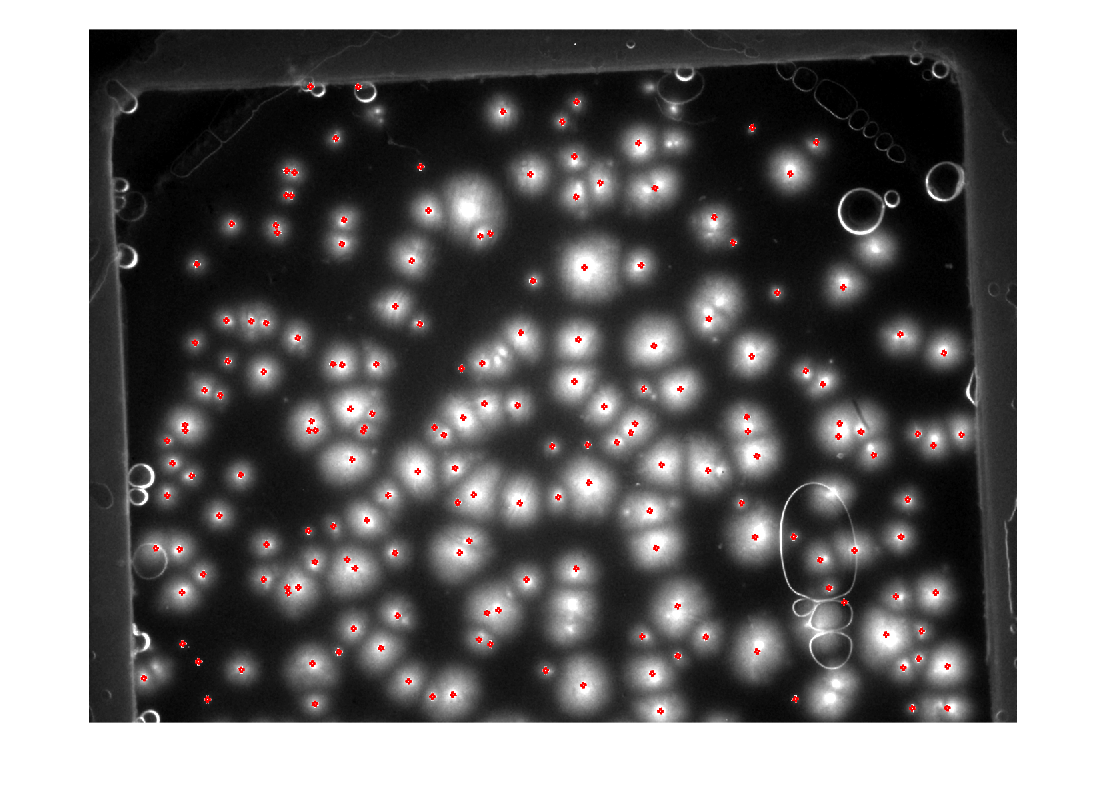

% Using model 'net' to predict # of dots in each imgEachDot

predictionDatasetPath = [pwd '/Prediction'];

imdsPred = imageDatastore(predictionDatasetPath, ...
    'IncludeSubfolders',true);

Pred = classify(net,imdsPred);
doublePred = double(Pred) - 1; % adjust for automatic increment upon using double()

% Label counted signals on original pic
centers_all_afterNN = bsxfun(@times,centers_all,doublePred);
centers_all_afterNN_nonzero = centers_all_afterNN(any(centers_all_afterNN,2),:);

figure(10)
imshow(A_crop)
radii_all = 3*ones(size(centers_all_afterNN_nonzero,1),1);
viscircles(centers_all_afterNN_nonzero,radii_all);

numSignals = size(centers_all_afterNN_nonzero,1)

numSignals = 180


% % Remove false positive dots' neighbourhood signal counts
% falsePositiveNeighbours = transpose(centers_all_rounded(:,3)) ...
%     * doublePred;
% 
% % Report total number of dots
% sum(doublePred) - falsePositiveNeighbours